%Sinal de Entrada
tx0 = -2:0.01:-1;
tx1 = -1:0.01:0.5;
tx2 = 0.5:0.01:3;
tx3 = 3:0.01:10;
x0 = zeros(size(tx0));
x1 = 0.6*ones(size(tx1));
x2 = 0.3*ones(size(tx2));
x3 = zeros(size(tx3));
x = [x0 x1 x2 x3];
tx = [tx0 tx1 tx2 tx3];
figure 
plot(tx, x)
hold on

%Resposta Impulsiva 
th1 = 0:0.01:10;
h1 = exp(-th1);
h = [0 h1];
th = [0 th1];
plot(th, h)
hold off


%Sem sobreposicao
t = -1;
figure
plot(tx, x, t - th, h)
legend("x(\tau)", "h(-1-\tau)")


%Sobreposicao parcial
t = 0.5;
figure
plot(tx, x, t - th, h)
legend("x(\tau)", "h(0.5-\tau)")

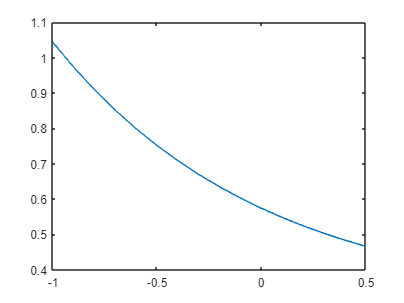


%Sobreposicao total
t = 3;
figure
plot(tx, x, t - th, h)
legend("x(\tau)", "h(3-\tau)")


%Determinando as integrais
syms t r
%Inicio da sobreposicao

int1 = int(0.6*exp(r-t), r, -1, 0.5)

$$int1 = \frac{3\,{\mathrm{e}}^{-t-1}\,\left({\mathrm{e}}^{3/2}-1\right)}{5}$$


%Sobreposicao completa
int2 = int(0.6*exp(r - t), r, -1, 0.5) + int(0.3*exp(r-t), r, 0.5, t)

$$int2 = \frac{3\,{\mathrm{e}}^{-t-1}\,\left({\mathrm{e}}^{3/2}-1\right)}{5}-\frac{3\,{\mathrm{e}}^{-t}\,\sqrt{\mathrm{e}}}{10}+\frac{3}{10}$$


%Sobreposicao estagio saida
int3 = int(0.6*exp(r-t), r, -1, 0.5) + int(0.3*exp(r-t), r, 0.5, 3)

$$int3 = \frac{3\,{\mathrm{e}}^{-t-1}\,\left({\mathrm{e}}^{3/2}-1\right)}{5}+\frac{3\,{\mathrm{e}}^{-t}\,\sqrt{\mathrm{e}}\,\left({\mathrm{e}}^{5/2}-1\right)}{10}$$


ts1 = -1:0.1:0.5;
ts2 = 0.5:0.1:3;
ts3 = 3:0.1:10;

%y1 = subs(int1, t, ts1);
y1 = (3*exp((- ts1 - 1))*(exp(3/2) - 1))/5

y1 =     2.0890    1.8902    1.7103    1.5476    1.4003    1.2671    1.1465    1.0374    0.9387    0.8493    0.7685    0.6954    0.6292    0.5693    0.5151    0.4661


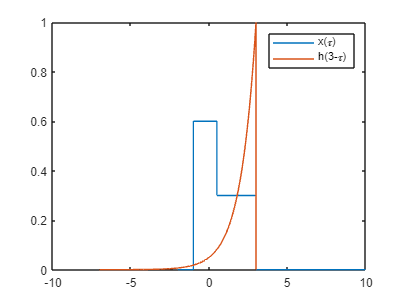


%y2 = subs(int2, t, ts2);
y2 = (3*exp((- t - 1))*(exp(3/2)) - 1)/5 - (3*exp((-t))*sqrt(exp(1)))/10 + 3/10;
%y3 = subs(int3, t, ts3);

%ys1 = [y1 y2 y3];
ts = [ts1 ts2 ts3];
ys1 = [y1 y2 y3];

%plot(ts, ys1)


%Exercicio 2
t0 = 0:0.01:1-0.01;
t1 = 1:0.01:2;
t2 = 2.01:0.01:10;
t = [t0 t1 t2];

%Sinal entrada
x0 = zeros(size(t0));
x1 = ones(size(t1));
x2 = zeros(size(t2));
x = [x0 x1 x2];

%Resposta impulsiva
h0 = zeros(size(t0));
h1 = ones(size(t1));
h2 = zeros(size(t2));
h = [h0 h1 h2];

%Convolução 
ys2=conv(x, h)*0.01;

% Exercicio 3
th = 0:0.01:4;
h = cos(2*pi*th);
%Definindo a x(t)
t1 = 0:0.01:1;
t2 = 1.01:0.01:2;
t3 = 2.01:0.01:4;
x1 = 2.*t1;
x2 = -2.*t2 + 4;
x3 = zeros(size(t3));
tx = [t1 t2 t3];
x = [x1 x2 x3];
plot(tx, x)
ys3 = conv(x, h) * 0.01;
ts3 = 0:0.01:8;
plot(ts3, ys3)